# Teoria i Metody Optymalizacji – Część A: minimalizacja funkcji jednej zmiennej

Skrypt realizuje część A zadania projektowego: trzy algorytmy minimalizacji funkcji jednej zmiennej – **(i) metodę złotego podziału**, **(ii) metodę gradientu** i **(iii) metodę aproksymacji kwadratowej Powella** – przetestowane na czterech funkcjach celu, w tym na „trudnych przypadkach”: funkcji multimodalnej, minimum leżącym na ograniczeniu i funkcji nieróżniczkowalnej w minimum.

**Jak korzystać.** Uruchom cały skrypt (*Run*, F5). Każda sekcja metody ma własne kontrolki – listę funkcji, parametry metody i suwak iteracji *k*. Zmiana kontrolki automatycznie przelicza i przerysowuje tylko tę sekcję. Lewy górny wykres pokazuje stan algorytmu po *k* iteracjach, prawy – stan końcowy, dolny – zbieżność. Sekcja 6 otwiera osobne okno eksploratora z animacją i możliwością wpisania własnej funkcji.

Wszystkie funkcje pomocnicze znajdują się na końcu pliku, więc skrypt nie wymaga dodatkowych plików (MATLAB R2019b lub nowszy).

## 1. Funkcje celu

Zestaw testowy. Przedział $[a,b]$ jest jednocześnie ograniczeniem $x \in [a,b]$.

• **f1 – unimodalna:** $f_1(x) = (x-2)^2 + 0.5\,e^{0.3x}$, $x\in[-1,\,5]$ – przypadek „łatwy”, ograniczenia nieaktywne.

• **f2 – multimodalna:** $f_2(x) = x^4 - 4x^2 + x$, $x\in[-2.5,\,2.5]$ – minimum globalne $x\approx-1.47$ i lokalne $x\approx1.35$.

• **f3 – minimum na ograniczeniu:** $f_3(x) = (x-4)^2 + \sin 2x$, $x\in[0,\,3]$ – minima bez ograniczeń ($x\approx3.03$ i $x\approx4.92$) leżą poza przedziałem, rozwiązaniem jest brzeg $x = 3$.

• **f4 – nieróżniczkowalna:** $f_4(x) = |x-1| + 0.3x^2$, $x\in[-2,\,3]$ – minimum $x = 1$ w punkcie załamania, w którym pochodna nie istnieje.

Zielone pole to zbiór dopuszczalny $[a,b]$, gwiazdka – minimum referencyjne (globalne na $[a,b]$, wyznaczone na gęstej siatce i doprecyzowane), kwadrat – domyślny punkt startowy $x_0$ dla gradientu i metody Powella.

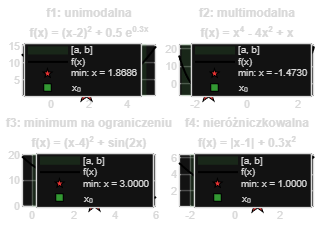

F = funkcje_testowe();
figure('Name', 'Funkcje celu', 'Color', 'w', 'Position', [100 100 1100 750]);
t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:numel(F)
    ax = nexttile(t);  hold(ax, 'on');  grid(ax, 'on');  box(ax, 'on');
    xx = linspace(F(i).xplot(1), F(i).xplot(2), 800);
    yy = wartosci(F(i).f, xx);
    yl = [min(yy) max(yy)] + [-0.05 0.05]*(max(yy) - min(yy));
    patch(ax, [F(i).a F(i).b F(i).b F(i).a], yl([1 1 2 2]), [0.3 0.75 0.3], ...
          'FaceAlpha', 0.12, 'EdgeColor', 'none');
    plot(ax, xx, yy, 'k-', 'LineWidth', 1.5);
    [xr, fr] = minimum_ref(F(i));
    plot(ax, xr, fr, 'p', 'MarkerSize', 14, 'MarkerFaceColor', [0.9 0.2 0.2], 'MarkerEdgeColor', 'k');
    plot(ax, F(i).x0, F(i).f(F(i).x0), 's', 'MarkerSize', 8, ...
         'MarkerFaceColor', [0.2 0.6 0.2], 'MarkerEdgeColor', 'k');
    hold(ax, 'off');  xlim(ax, F(i).xplot);  ylim(ax, yl);
    title(ax, {F(i).nazwa, ['f(x) = ' F(i).wzor]});
    legend(ax, {'[a, b]', 'f(x)', sprintf('min: x = %.4f', xr), 'x_0'}, 'Location', 'best');
end

## 2. Metoda złotego podziału

Metoda bezgradientowa dla funkcji unimodalnej na $[a,b]$. W przedziale wybiera się dwa punkty


$$x_1 = b - \tau(b-a),\qquad x_2 = a + \tau(b-a),\qquad \tau = \frac{\sqrt{5}-1}{2}\approx 0.618$$


Jeśli $f(x_1) > f(x_2)$, minimum leży w $[x_1,\,b]$, w przeciwnym razie w $[a,\,x_2]$. Dzięki proporcji złotego podziału jeden z punktów przechodzi do następnej iteracji, więc na iterację przypada tylko **jedno** nowe obliczenie $f$, a przedział maleje $\tau$-krotnie:


$$b_k - a_k = \tau^k\,(b_0-a_0)\quad\Rightarrow\quad k \ge \frac{\ln\left(\mathrm{tol}/(b_0-a_0)\right)}{\ln\tau}$$


Ograniczenie $x\in[a,b]$ jest spełnione z definicji metody. Dla funkcji multimodalnej metoda znajduje *któreś* minimum lokalne – które, zależy od przedziału (sprawdź f2 z przedziałem `[-1 2.5]`).

**Na wykresie:** poziome paski pod krzywą to kolejne przedziały $[a_k,\,b_k]$ (od jasnych do ciemnych), żółte pole – bieżący przedział, kółko i kwadrat – punkty $x_1$, $x_2$, gwiazdka – najlepszy punkt.

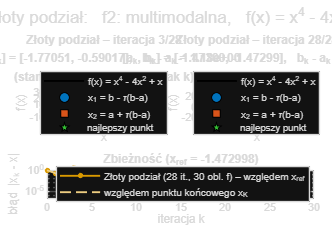

Złoty podział – f2: multimodalna
   x*      = -1.47299743      f(x*) = -5.44419207
   x_ref   = -1.47299761      f_ref = -5.44419207   (minimum globalne na [a,b])
   |x*-x_ref| = 1.76e-07,  iteracje = 28,  obliczenia f = 30
   kryterium stopu: długość przedziału 7.04e-06 <= tol


nrF = 2;   % funkcja celu
ab  = [];   % własny przedział [a b]; [] = domyślny z definicji funkcji
tol = 1e-5;   % tolerancja = końcowa długość przedziału
k   = 3;   % iteracja pokazana na lewym wykresie

if ~exist('F', 'var'), F = funkcje_testowe(); end
par = domyslne_parametry();   par.tol = tol;
Fi  = F(nrF);
if numel(ab) == 2, Fi.a = min(ab);  Fi.b = max(ab); end
Wz  = pokaz_metode(Fi, 'zloty', k, par);

## 3. Metoda gradientu

Metoda najszybszego spadku w 1D – krok w kierunku przeciwnym do pochodnej. Dla zadania z ograniczeniami stosowany jest **gradient rzutowany**:


$$x_{k+1} = P_{[a,b]}\left(x_k - \alpha_k f'(x_k)\right),\qquad P_{[a,b]}(x) = \min\left(\max(x,a),\,b\right)$$


Pochodna liczona jest numerycznie różnicą centralną $f'(x)\approx\frac{f(x+h)-f(x-h)}{2h}$, więc metoda działa dla dowolnej funkcji (koszt: 2 obliczenia $f$ na pochodną). Długość kroku jest stała ($\alpha_k=\alpha$) albo dobierana metodą *backtracking* – krok jest połowiony, dopóki nie zachodzi warunek Armijo:


$$f(x_{k+1}) \le f(x_k) + c_1\, f'(x_k)\,(x_{k+1}-x_k),\qquad c_1 = 10^{-4}$$


Kryteria stopu: $|f'(x_k)| < \mathrm{tol}$ albo $|x_{k+1}-x_k| < \mathrm{tol}$. Drugie wykrywa także minimum na ograniczeniu, gdzie pochodna jest niezerowa, ale rzut zatrzymuje ruch.

**Warto sprawdzić:** f2 ze startem `x0 = 0.5` i `x0 = -0.5` (dwa różne minima); f4 bez Armijo (oscylacje wokół załamania); f2 bez Armijo z $\alpha = 0.3$ (za duży krok – brak zbieżności); f3 bez ograniczeń (wyjście poza $[0,3]$).

**Na wykresie:** kolejne punkty $x_k$ (od jasnych do ciemnych), czerwona styczna o nachyleniu $f'(x_k)$.

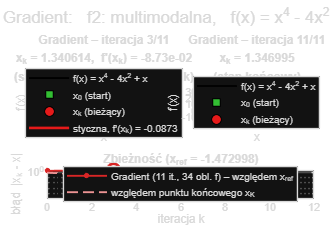

Gradient – f2: multimodalna
   x*      = 1.34699484      f(x*) = -2.61855598
   x_ref   = -1.47299761      f_ref = -5.44419207   (minimum globalne na [a,b])
   |x*-x_ref| = 2.82e+00,  iteracje = 11,  obliczenia f = 34
   kryterium stopu: |x(k+1)-x(k)| = 9.37e-06 < tol


nrF    = 2;   % funkcja celu
x0     = [];   % punkt startowy; [] = domyślny
alfa   = 0.1;   % krok (przy Armijo: krok początkowy)
armijo = true;   % dobór kroku warunkiem Armijo
ogr    = true;   % ograniczenia a <= x <= b
k      = 3;   % iteracja pokazana na lewym wykresie

if ~exist('F', 'var'), F = funkcje_testowe(); end
par = domyslne_parametry();
par.alfa = alfa;   par.armijo = armijo;   par.ograniczenia = ogr;
Fi = F(nrF);
if isscalar(x0), Fi.x0 = x0; end
Wg = pokaz_metode(Fi, 'gradient', k, par);

## 4. Metoda aproksymacji kwadratowej Powella

Funkcję przybliża się parabolą przechodzącą przez trzy punkty, a za nowy punkt przyjmuje wierzchołek paraboli. Punkty startowe: $x_1 = x_0$, $x_2 = x_1 + \Delta$, a $x_3 = x_1 + 2\Delta$, gdy $f(x_2)\le f(x_1)$, w przeciwnym razie $x_3 = x_1 - \Delta$. Dla uporządkowanych punktów $x_1 < x_2 < x_3$:


$$c_1 = \frac{f_2-f_1}{x_2-x_1},\qquad c_2 = \frac{1}{x_3-x_2}\left(\frac{f_3-f_1}{x_3-x_1} - c_1\right),\qquad x^* = \frac{x_1+x_2}{2} - \frac{c_1}{2c_2}$$


Z czterech punktów $\{x_1, x_2, x_3, x^*\}$ zostaje najlepszy i jego dwaj sąsiedzi, co utrzymuje minimum „w okrążeniu”. Zabezpieczenia: gdy $c_2 \le 0$ (parabola wklęsła – wierzchołek byłby maksimum), wykonywany jest krok w stronę mniejszych wartości $f$; przy ograniczeniach $x^*$ jest rzutowany na $[a,b]$. Kryterium stopu: $|x^* - x_{best}| < \mathrm{tol}$.

Dla funkcji gładkich metoda zbiega nadliniowo (kilka iteracji), ale traci tę zaletę, gdy parabola źle przybliża funkcję – np. f4 z załamaniem w minimum.

**Na wykresie:** pomarańczowa parabola z bieżącej iteracji, blade – z poprzednich, gwiazdka – nowy punkt $x^*$.

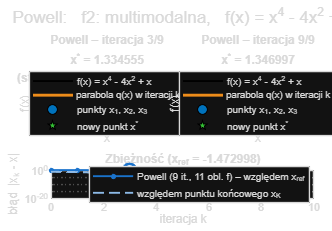

Powell – f2: multimodalna
   x*      = 1.34699423      f(x*) = -2.61855598
   x_ref   = -1.47299761      f_ref = -5.44419207   (minimum globalne na [a,b])
   |x*-x_ref| = 2.82e+00,  iteracje = 9,  obliczenia f = 11
   kryterium stopu: |x* - x_best| = 2.34e-06 < tol


nrF   = 2;   % funkcja celu
x0    = [];   % punkt startowy; [] = domyślny
delta = 0.5;   % krok startowy
ogr   = true;   % ograniczenia a <= x <= b
k     = 3;   % iteracja pokazana na lewym wykresie

if ~exist('F', 'var'), F = funkcje_testowe(); end
par = domyslne_parametry();
par.delta = delta;   par.ograniczenia = ogr;
Fi = F(nrF);
if isscalar(x0), Fi.x0 = x0; end
Wp = pokaz_metode(Fi, 'powell', k, par);

## 5. Porównanie metod na wszystkich funkcjach

Wszystkie trzy metody z parametrami domyślnymi: $\mathrm{tol} = 10^{-5}$, $\alpha = 0.1$ z warunkiem Armijo, $\Delta = 0.5$, z ograniczeniami. Błąd liczony jest względem minimum globalnego na $[a,b]$.

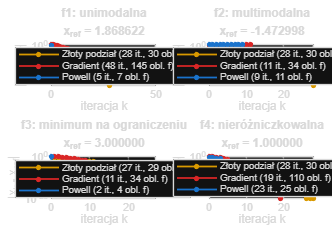

if ~exist('F', 'var'), F = funkcje_testowe(); end
par = domyslne_parametry();
metody  = {'zloty', 'gradient', 'powell'};
wiersze = cell(0, 8);
figure('Name', 'Porównanie zbieżności', 'Color', 'w', 'Position', [100 100 1150 800]);
t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:numel(F)
    [xr, fr] = minimum_ref(F(i));
    Ws = cell(1, 3);
    for j = 1:3
        W = uruchom_metode(metody{j}, F(i), par);   Ws{j} = W;
        wiersze(end+1, :) = {F(i).nazwa, W.metoda, W.xopt, W.fopt, ...
                             abs(W.xopt - xr), W.iter, W.nf, W.stop}; %#ok<SAGROW>
    end
    ax = nexttile(t);
    rysuj_zbieznosc(ax, Ws, xr);
    title(ax, {F(i).nazwa, sprintf('x_{ref} = %.6f', xr)});
end

T = cell2table(wiersze, 'VariableNames', ...
    {'Funkcja', 'Metoda', 'x_opt', 'f_opt', 'Blad_x', 'Iteracje', 'Obliczenia_f', 'Kryterium_stopu'})

T = 12×8 table
                Funkcja                     Metoda           x_opt      f_opt       Blad_x      Iteracje    Obliczenia_f                        Kryterium_stopu                     
    _______________________________    _________________    _______    _______    __________    ________    ____________    ________________________________________________________

    {'f1: unimodalna'             }    {'Złoty podział'}     1.8686    0.89311    2.7991e-07       28            30         {'długość przedziału 8.44e-06 <= tol'                  }
    {'f1: unimodalna'             }    {'Gradient'     }     1.8686    0.89311    3.3338e-05       48           145         {'|x(k+1)-x(k)| = 8.75e-06 < tol'            

**Z ograniczeniami czy bez?** Dla f3 z ograniczeniem $x\in[0,3]$ obie metody zatrzymują się na brzegu $x = 3$. Bez ograniczenia schodzą do minimum lokalnego $x \approx 3.026$, które jest niedopuszczalne.

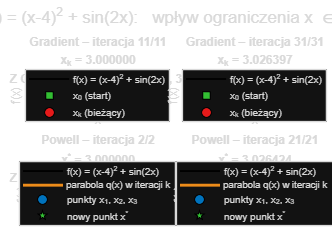

Fi   = F(3);
parZ = domyslne_parametry();               % z ograniczeniami
parB = parZ;   parB.ograniczenia = false;  % bez ograniczeń
figure('Name', 'Ograniczenia – f3', 'Color', 'w', 'Position', [100 100 1150 800]);
t = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, ['f_3(x) = ' Fi.wzor ':   wpływ ograniczenia x \in [0, 3]']);
for m = {'gradient', 'powell'}
    WZ = uruchom_metode(m{1}, Fi, parZ);
    WB = uruchom_metode(m{1}, Fi, parB);
    rysuj_metode(nexttile(t), Fi, WZ, WZ.iter, parZ, 'Z OGRANICZENIEM  x \in [0, 3]');
    rysuj_metode(nexttile(t), Fi, WB, WB.iter, parB, 'BEZ OGRANICZENIA');
end

## 6. Interaktywny eksplorator

Osobne okno z pełną kontrolą: wybór funkcji (albo własnej, np. `sin(3*x) + 0.1*x.^2`), metody (albo wszystkich trzech naraz), przedziału, punktu startowego i parametrów. Suwak przewija iteracje, a przycisk **▶ Animuj** odtwarza przebieg algorytmu krok po kroku (ponowne kliknięcie zatrzymuje animację).

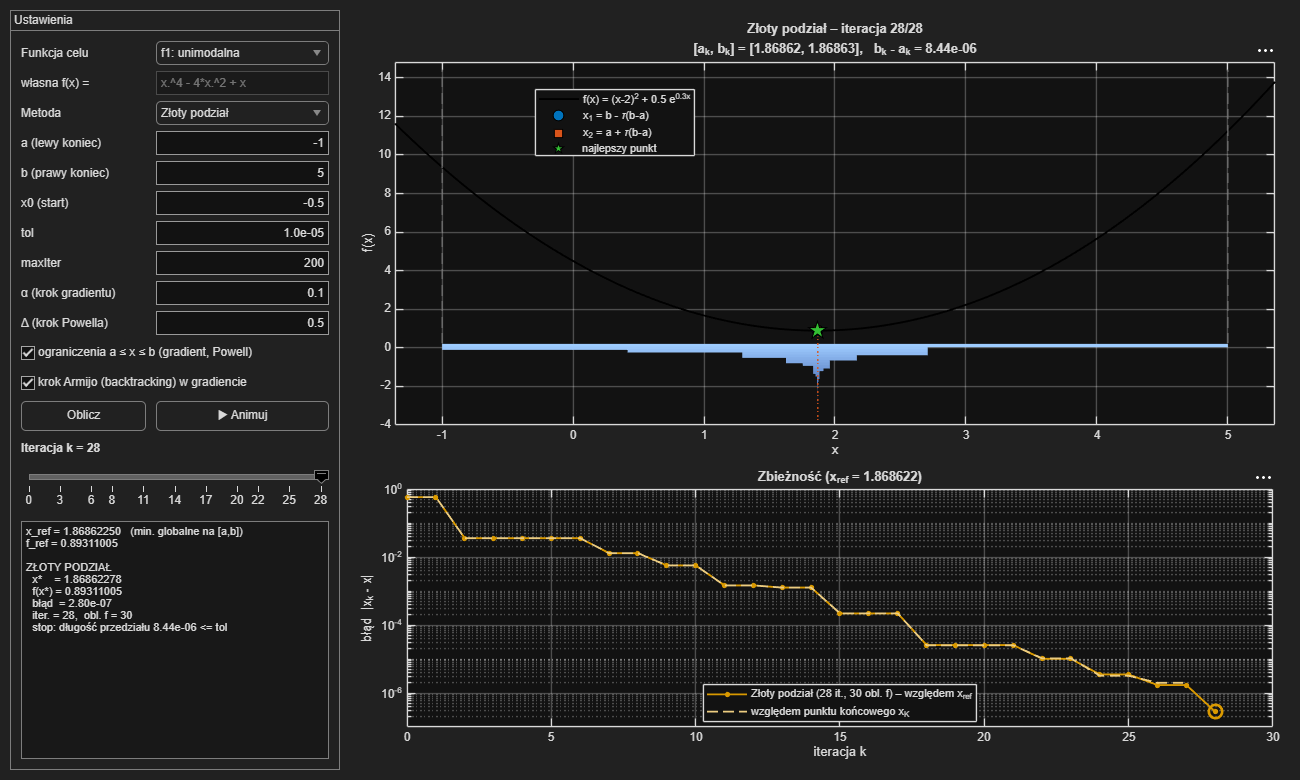

 
if ~exist('F', 'var'), F = funkcje_testowe(); end
eksplorator(F, domyslne_parametry());

## 7. Wnioski (parametry domyślne)

• **Złoty podział** jest najbardziej niezawodny: zbiega na wszystkich funkcjach, także na nieróżniczkowalnej f4 i z minimum na brzegu (f3), liniowo z ilorazem $\tau\approx0.618$ – 27–28 iteracji i 29–30 obliczeń $f$ dla $\mathrm{tol}=10^{-5}$. Wymaga jednak unimodalności na $[a,b]$: dla f2 trafił w minimum globalne tylko dzięki symetrycznemu przedziałowi $[-2.5,\,2.5]$; na $[-1,\,2.5]$ zbiega do minimum lokalnego $x\approx1.347$.

• **Metoda gradientu** jest najdroższa (pochodna numeryczna: 34–145 obliczeń $f$) i lokalna: dla f2 z $x_0 = 0.5$ trafia w minimum lokalne $x\approx1.347$, z $x_0=-0.5$ – w globalne. Dla f1 zatrzymała się z błędem $3\cdot10^{-5} > \mathrm{tol}$ – przy zbieżności liniowej warunek $|x_{k+1}-x_k|<\mathrm{tol}$ nie gwarantuje błędu mniejszego niż tol. Ze stałym krokiem jest wrażliwa na $\alpha$: f2 przy $\alpha=0.3$ nie zbiega, f4 przy $\alpha=0.1$ oscyluje wokół załamania (200 iteracji bez spełnienia kryterium); z warunkiem Armijo oba przypadki zbiegają.

• **Metoda Powella** jest najszybsza dla funkcji gładkich: f1 w 5 iteracjach (7 obliczeń $f$), f3 w 2 iteracjach (wierzchołek rzutowany na brzeg). Na f4 potrzebowała 23 iteracji i dała największy błąd ($2.8\cdot10^{-5}$), bo parabola źle przybliża załamanie. Jest metodą lokalną (f2 → $x\approx1.347$).

• **Ograniczenia:** rzut na $[a,b]$ w gradiencie i metodzie Powella poprawnie wyznacza minimum na brzegu (f3: $x^*=3$). Bez ograniczeń obie metody kończą w niedopuszczalnym punkcie $x\approx3.026$.

## Funkcje lokalne

**Algorytmy.** Każda metoda zwraca strukturę z wynikiem (`xopt`, `fopt`, `iter`, `nf`, `stop`) i pełną historią iteracji (`xk`, `fk`, `hist`), wykorzystywaną do rysowania.

function W = zloty_podzial(f, a, b, tol, maxIter)
% ZLOTY_PODZIAL  Minimalizacja funkcji jednej zmiennej metodą złotego podziału.
%   W = zloty_podzial(f, a, b, tol, maxIter)
%   f       – uchwyt do funkcji celu f(x)
%   [a,b]   – przedział poszukiwań (jednocześnie ograniczenie x ∈ [a,b])
%   tol     – wymagana długość końcowego przedziału
%   maxIter – maksymalna liczba iteracji
%   W       – struktura z wynikiem i pełną historią iteracji
tau = (sqrt(5) - 1)/2;                 % 0.618... – współczynnik złotego podziału
x1 = b - tau*(b - a);   f1 = f(x1);
x2 = a + tau*(b - a);   f2 = f(x2);
nf = 2;

H = [a b x1 x2 f1 f2];                 % historia: [a b x1 x2 f(x1) f(x2)]
k = 0;
while (b - a) > tol && k < maxIter
    k = k + 1;
    if f1 > f2                         % minimum leży w [x1, b]
        a  = x1;
        x1 = x2;  f1 = f2;
        x2 = a + tau*(b - a);  f2 = f(x2);
    else                               % minimum leży w [a, x2]
        b  = x2;
        x2 = x1;  f2 = f1;
        x1 = b - tau*(b - a);  f1 = f(x1);
    end
    nf = nf + 1;                       % tylko JEDNO nowe obliczenie f na iterację
    H(end+1, :) = [a b x1 x2 f1 f2]; %#ok<AGROW>
end

% przybliżenie minimum w każdej iteracji = lepszy z dwóch punktów wewnętrznych
lepszy = H(:,5) <= H(:,6);
xk = H(:,4);  xk(lepszy) = H(lepszy,3);
fk = H(:,6);  fk(lepszy) = H(lepszy,5);

W.metoda = 'Złoty podział';
W.hist   = H;
W.xk     = xk;
W.fk     = fk;
W.xopt   = xk(end);
W.fopt   = fk(end);
W.iter   = k;
W.nf     = nf;
if (b - a) <= tol
    W.stop = sprintf('długość przedziału %.2e <= tol', b - a);
else
    W.stop = 'osiągnięto maxIter';
end
end

function W = metoda_gradientu(f, x0, alfa, tol, maxIter, lb, ub, armijo)
% METODA_GRADIENTU  Metoda najszybszego spadku (gradientu) dla funkcji 1D.
%   W = metoda_gradientu(f, x0, alfa, tol, maxIter, lb, ub, armijo)
%   x0      – punkt startowy
%   alfa    – długość kroku (przy armijo=true: krok początkowy)
%   lb, ub  – ograniczenia; [-Inf, Inf] = zadanie bez ograniczeń.
%             Przy ograniczeniach stosowany jest gradient RZUTOWANY:
%             x(k+1) = P[lb,ub]( x(k) - alfa*f'(x(k)) )
%   armijo  – true: krok dobierany przez backtracking (warunek Armijo),
%             false: stały krok alfa
% Pochodna liczona numerycznie (różnica centralna), więc metoda działa
% dla dowolnej funkcji podanej uchwytem.
P  = @(x) min(max(x, lb), ub);         % rzut na zbiór dopuszczalny
c1 = 1e-4;                             % stała w warunku Armijo

x  = P(x0);   fx = f(x);   nf = 1;
xk = x;  fk = fx;  gk = [];  ak = [];
stop = 'osiągnięto maxIter';
k = 0;
while k < maxIter
    h = 1e-6*max(1, abs(x));
    g = (f(x + h) - f(x - h))/(2*h);   nf = nf + 2;
    gk(end+1) = g; %#ok<AGROW>
    if abs(g) < tol
        stop = sprintf('|f''(x)| = %.2e < tol', abs(g));
        break
    end
    t = alfa;
    xn = P(x - t*g);   fn = f(xn);   nf = nf + 1;
    if armijo                          % backtracking: t <- t/2
        nb = 0;
        while fn > fx + c1*g*(xn - x) && nb < 40
            t = t/2;  nb = nb + 1;
            xn = P(x - t*g);  fn = f(xn);  nf = nf + 1;
        end
    end
    k  = k + 1;
    ak(end+1) = t; %#ok<AGROW>
    dx = abs(xn - x);
    x  = xn;  fx = fn;
    xk(end+1) = x;  fk(end+1) = fx; %#ok<AGROW>
    if ~isfinite(x) || abs(x) > 1e8
        stop = 'rozbieżność (krok za duży)';
        break
    end
    if dx < tol
        if x == lb || x == ub
            stop = sprintf('krok rzutowany < tol – minimum na ograniczeniu x = %g', x);
        else
            stop = sprintf('|x(k+1)-x(k)| = %.2e < tol', dx);
        end
        break
    end
end

W.metoda = 'Gradient';
W.xk   = xk(:);
W.fk   = fk(:);
W.gk   = gk(:);
W.ak   = ak(:);
W.hist = [W.xk W.fk];
W.xopt = x;
W.fopt = fx;
W.iter = k;
W.nf   = nf;
W.stop = stop;
W.lb = lb;  W.ub = ub;
end

function W = powell_kwadr(f, x0, delta, tol, maxIter, lb, ub)
% POWELL_KWADR  Metoda aproksymacji kwadratowej Powella (funkcja 1D).
%   W = powell_kwadr(f, x0, delta, tol, maxIter, lb, ub)
%   x0     – punkt startowy,  delta – krok do wyznaczenia punktów startowych
%   lb, ub – ograniczenia ([-Inf, Inf] = brak ograniczeń); punkt
%            wyznaczony z paraboli jest rzutowany na [lb, ub]
% W każdej iteracji przez 3 punkty prowadzona jest parabola
%   q(x) = f1 + c1(x - x1) + c2(x - x1)(x - x2),
% a jej wierzchołek  x* = (x1 + x2)/2 - c1/(2 c2)  staje się nowym punktem.
% Spośród 4 punktów odrzucany jest ten o największej wartości f.
P = @(x) min(max(x, lb), ub);

% --- trzy punkty startowe (jak w klasycznym algorytmie Powella) ---
x1 = P(x0);           f1 = f(x1);
x2 = P(x1 + delta);
if x2 == x1, x2 = P(x1 - delta); end
f2 = f(x2);
if f2 <= f1, x3 = P(x1 + 2*(x2 - x1)); else, x3 = P(x1 - (x2 - x1)); end
if any(abs(x3 - [x1 x2]) < eps(max(1, abs(x3))))      % kolizja na ograniczeniu
    x3 = (x1 + x2)/2;
end
f3 = f(x3);   nf = 3;
X = [x1 x2 x3];   F = [f1 f2 f3];

H = struct('X', {}, 'F', {}, 'c1', {}, 'c2', {}, 'xn', {}, 'fn', {});
[F0, i0] = min(F);
xk = X(i0);   fk = F0;
stop = 'osiągnięto maxIter';
k = 0;
while k < maxIter
    k = k + 1;
    [X, s] = sort(X);  F = F(s);
    c1 = (F(2) - F(1))/(X(2) - X(1));
    c2 = ((F(3) - F(1))/(X(3) - X(1)) - c1)/(X(3) - X(2));
    [fb, ib] = min(F);   xb = X(ib);
    if c2 > 0                                      % parabola wypukła – wierzchołek
        xn = (X(1) + X(2))/2 - c1/(2*c2);
    else                                           % parabola wklęsła/prosta –
        L = X(3) - X(1);                           % krok w stronę mniejszych f
        if F(1) <= F(3), xn = X(1) - 2*L; else, xn = X(3) + 2*L; end
    end
    xn = P(xn);
    if abs(xn - xb) < tol                          % warunek stopu
        H(end+1) = struct('X', X, 'F', F, 'c1', c1, 'c2', c2, 'xn', xn, 'fn', fb); %#ok<AGROW>
        xk(end+1) = xb;  fk(end+1) = fb; %#ok<AGROW>
        stop = sprintf('|x* - x_best| = %.2e < tol', abs(xn - xb));
        break
    end
    fn = f(xn);   nf = nf + 1;
    H(end+1) = struct('X', X, 'F', F, 'c1', c1, 'c2', c2, 'xn', xn, 'fn', fn); %#ok<AGROW>
    % zamiana punktów: z 4 punktów (posortowanych) zostaje najlepszy i jego
    % dwaj sąsiedzi – dzięki temu zachowane jest „otoczenie” minimum
    % (przedział zawierający minimum nie może się powiększyć)
    [X4, s] = sort([X xn]);  F4 = [F fn];  F4 = F4(s);
    [~, ib] = min(F4);
    ib = min(max(ib, 2), 3);
    Xn = X4(ib-1:ib+1);   Fn = F4(ib-1:ib+1);
    if isequal(Xn, X) || numel(unique(Xn)) < 3
        X = Xn;  F = Fn;
        [fb, ib] = min(F);
        xk(end+1) = X(ib);  fk(end+1) = fb; %#ok<AGROW>
        stop = 'brak postępu – zbiór punktów się nie zmienia';
        break
    end
    X = Xn;  F = Fn;
    [fb, ib] = min(F);
    xk(end+1) = X(ib);  fk(end+1) = fb; %#ok<AGROW>
end

W.metoda = 'Powell';
W.hist = H;
W.xk   = xk(:);
W.fk   = fk(:);
W.xopt = xk(end);
W.fopt = fk(end);
W.iter = k;
W.nf   = nf;
W.stop = stop;
W.lb = lb;  W.ub = ub;
end

function W = uruchom_metode(metoda, Fi, par)
% URUCHOM_METODE  Wywołuje wybraną metodę dla funkcji Fi z parametrami par.
%   metoda: 'zloty' | 'gradient' | 'powell'
if par.ograniczenia
    lb = Fi.a;  ub = Fi.b;
else
    lb = -Inf;  ub = Inf;
end
switch lower(metoda)
    case 'zloty'          % złoty podział zawsze pracuje na przedziale [a,b]
        W = zloty_podzial(Fi.f, Fi.a, Fi.b, par.tol, par.maxIter);
    case 'gradient'
        W = metoda_gradientu(Fi.f, Fi.x0, par.alfa, par.tol, par.maxIter, lb, ub, par.armijo);
    case 'powell'
        W = powell_kwadr(Fi.f, Fi.x0, par.delta, par.tol, par.maxIter, lb, ub);
    otherwise
        error('Nieznana metoda: %s', metoda);
end
W.klucz = lower(metoda);
end

function par = domyslne_parametry()
% DOMYSLNE_PARAMETRY  Wspólne, domyślne parametry wszystkich metod.
par.tol          = 1e-5;   % tolerancja: długość przedziału / krok / |f'(x)|
par.maxIter      = 200;    % maksymalna liczba iteracji
par.alfa         = 0.1;    % krok metody gradientu (przy Armijo – krok początkowy)
par.armijo       = true;   % true – krok Armijo (backtracking), false – krok stały
par.delta        = 0.5;    % krok startowy metody Powella
par.ograniczenia = true;   % gradient/Powell: true – x ∈ [a,b], false – bez ograniczeń
end

function F = funkcje_testowe()
% FUNKCJE_TESTOWE  Zestaw funkcji celu do testowania algorytmów 1D.
%   Każdy element: nazwa, f, przedział [a,b], punkt startowy x0, opis.
F = struct('nazwa', {}, 'wzor', {}, 'f', {}, 'a', {}, 'b', {}, 'x0', {}, 'opis', {}, 'xplot', {});

F(1).nazwa = 'f1: unimodalna';
F(1).wzor  = '(x-2)^2 + 0.5 e^{0.3x}';
F(1).f     = @(x) (x - 2).^2 + 0.5*exp(0.3*x);
F(1).a = -1;  F(1).b = 5;  F(1).x0 = -0.5;
F(1).xplot = [-1.5 5.5];      % zakres osi x na wykresie przeglądowym
F(1).opis  = 'gładka, wypukła, minimum wewnątrz [a,b] (ograniczenia nieaktywne)';

F(2).nazwa = 'f2: multimodalna';
F(2).wzor  = 'x^4 - 4x^2 + x';
F(2).f     = @(x) x.^4 - 4*x.^2 + x;
F(2).a = -2.5;  F(2).b = 2.5;  F(2).x0 = 0.5;
F(2).xplot = [-2.6 2.6];      % zakres osi x na wykresie przeglądowym
F(2).opis  = 'dwa minima lokalne: globalne x≈-1.47, lokalne x≈1.35';

F(3).nazwa = 'f3: minimum na ograniczeniu';
F(3).wzor  = '(x-4)^2 + sin(2x)';
F(3).f     = @(x) (x - 4).^2 + sin(2*x);
F(3).a = 0;  F(3).b = 3;  F(3).x0 = 0.5;
F(3).xplot = [-0.5 6];      % zakres osi x na wykresie przeglądowym
F(3).opis  = 'bez ograniczeń: minima x≈3.03 i x≈4.92 – oba poza [0,3] → rozwiązanie x = 3 (ograniczenie aktywne)';

F(4).nazwa = 'f4: nieróżniczkowalna';
F(4).wzor  = '|x-1| + 0.3x^2';
F(4).f     = @(x) abs(x - 1) + 0.3*x.^2;
F(4).a = -2;  F(4).b = 3;  F(4).x0 = 2.5;
F(4).xplot = [-2.5 3.5];      % zakres osi x na wykresie przeglądowym
F(4).opis  = 'minimum x = 1 w punkcie „załamania” – brak pochodnej w minimum';
end

function [xr, fr] = minimum_ref(Fi)
% MINIMUM_REF  Minimum referencyjne (globalne) na [a,b]: gęsta siatka + doprecyzowanie.
xx = linspace(Fi.a, Fi.b, 20001);
[~, i] = min(wartosci(Fi.f, xx));
h  = xx(2) - xx(1);
lo = max(Fi.a, xx(i) - h);  hi = min(Fi.b, xx(i) + h);
Z  = zloty_podzial(Fi.f, lo, hi, 1e-12, 200);
xr = Z.xopt;  fr = Z.fopt;
if Fi.f(Fi.a) < fr, xr = Fi.a; fr = Fi.f(xr); end
if Fi.f(Fi.b) < fr, xr = Fi.b; fr = Fi.f(xr); end
end

function y = wartosci(f, x)
% WARTOSCI  Wartości f w punktach x (działa także dla funkcji niewektorowych).
try
    y = f(x);
    if ~isequal(size(y), size(x)), y = arrayfun(f, x); end
catch
    y = arrayfun(f, x);
end
end

**Wizualizacja.**

function W = pokaz_metode(Fi, metoda, k, par)
% POKAZ_METODE  Uruchamia metodę i rysuje: stan po k iteracjach, stan końcowy
% oraz wykres zbieżności. Wypisuje podsumowanie w oknie poleceń.
W = uruchom_metode(metoda, Fi, par);
[xr, fr] = minimum_ref(Fi);
k = max(0, min(round(k), W.iter));
fig = figure('Name', [W.metoda ' – ' Fi.nazwa], 'Color', 'w', 'Position', [100 100 1150 800]);
t = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('%s:   %s,   f(x) = %s', W.metoda, Fi.nazwa, Fi.wzor));
rysuj_metode(nexttile(t), Fi, W, k, par, '(stan po k iteracjach – suwak k)');
rysuj_metode(nexttile(t), Fi, W, W.iter, par, '(stan końcowy)');
rysuj_zbieznosc(nexttile(t, [1 2]), {W}, xr, k);
fprintf('%s – %s\n', W.metoda, Fi.nazwa);
fprintf('   x*      = %.8f      f(x*) = %.8f\n', W.xopt, W.fopt);
fprintf('   x_ref   = %.8f      f_ref = %.8f   (minimum globalne na [a,b])\n', xr, fr);
fprintf('   |x*-x_ref| = %.2e,  iteracje = %d,  obliczenia f = %d\n', abs(W.xopt - xr), W.iter, W.nf);
fprintf('   kryterium stopu: %s\n', W.stop);
end

function rysuj_metode(ax, Fi, W, k, par, dopisek)
% RYSUJ_METODE  Rysuje stan metody W po k iteracjach na osiach ax.
%   k = 0 – stan początkowy, k = W.iter – stan końcowy.
%   dopisek – (opcjonalnie) dodatkowa linia tytułu
k  = max(0, min(round(k), W.iter));
xl = zakres_x(Fi, W);
cla(ax);  hold(ax, 'on');  grid(ax, 'on');  box(ax, 'on');
xx = linspace(xl(1), xl(2), 600);
yy = wartosci(Fi.f, xx);
hf = plot(ax, xx, yy, 'k-', 'LineWidth', 1.4);
yl = [min(yy) max(yy)];  dy = max(diff(yl), 1e-9);
% ograniczenia x ∈ [a,b] (dla złotego podziału – zawsze)
if par.ograniczenia || strcmp(W.klucz, 'zloty')
    cb = [0.45 0.45 0.45];             % ograniczenia aktywne w algorytmie
else
    cb = [0.82 0.82 0.82];             % bez ograniczeń – [a,b] tylko informacyjnie
end
pion(ax, Fi.a, yl, cb);
pion(ax, Fi.b, yl, cb);
switch W.klucz
    case 'zloty',    [h, lab, tyt] = rys_zloty(ax, Fi, W, k, yl, dy);
    case 'gradient', [h, lab, tyt] = rys_gradient(ax, Fi, W, k, xl, dy);
    case 'powell',   [h, lab, tyt] = rys_powell(ax, Fi, W, k, xl, yl, dy);
end
hold(ax, 'off');
xlim(ax, xl);
yy0 = get(ax, 'YLim');
ylim(ax, [min(yy0(1), yl(1) - 0.05*dy), yl(2) + 0.08*dy]);
xlabel(ax, 'x');  ylabel(ax, 'f(x)');
if nargin > 5 && ~isempty(dopisek), tyt = [tyt {dopisek}]; end
title(ax, tyt);
legend(ax, [hf h], [{['f(x) = ' Fi.wzor]} lab], 'Location', 'best');
end

% ======================================================================
function [h, lab, tyt] = rys_zloty(ax, Fi, W, k, yl, dy)
H  = W.hist;   n = size(H, 1) - 1;
% pasek każdego przedziału [a_i, b_i] pod wykresem funkcji
pas = 0.30*dy/max(n, 1);
for i = 0:k
    y = yl(1) - 0.06*dy - i*pas;
    plot(ax, H(i+1, 1:2), [y y], '-', 'Color', kolor(i, n), 'LineWidth', 2.5);
end
ak = H(k+1, 1);  bk = H(k+1, 2);
yb = yl(1) - 0.06*dy - k*pas;
patch('XData', [ak bk bk ak], 'YData', [yb yb yl(2) yl(2)], 'Parent', ax, ...
      'FaceColor', [1 0.85 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none');
x1 = H(k+1, 3);  x2 = H(k+1, 4);
plot(ax, [x1 x1], [yb H(k+1, 5)], ':', 'Color', [0 0.45 0.74]);
plot(ax, [x2 x2], [yb H(k+1, 6)], ':', 'Color', [0.85 0.33 0.1]);
h1 = plot(ax, x1, H(k+1, 5), 'o', 'MarkerSize', 8, 'MarkerFaceColor', [0 0.45 0.74], 'MarkerEdgeColor', 'k');
h2 = plot(ax, x2, H(k+1, 6), 's', 'MarkerSize', 8, 'MarkerFaceColor', [0.85 0.33 0.1], 'MarkerEdgeColor', 'k');
h3 = plot(ax, W.xk(k+1), W.fk(k+1), 'p', 'MarkerSize', 14, 'MarkerFaceColor', [0.2 0.75 0.2], 'MarkerEdgeColor', 'k');
h = [h1 h2 h3];
lab = {'x_1 = b - \tau(b-a)', 'x_2 = a + \tau(b-a)', 'najlepszy punkt'};
tyt = {sprintf('Złoty podział – iteracja %d/%d', k, W.iter), ...
       sprintf('[a_k, b_k] = [%.5f, %.5f],   b_k - a_k = %.2e', ak, bk, bk - ak)};
end

% ======================================================================
function [h, lab, tyt] = rys_gradient(ax, Fi, W, k, xl, dy)
n  = W.iter;
xs = W.xk(1:k+1);  fs = W.fk(1:k+1);
plot(ax, xs, fs, '-', 'Color', [0.6 0.6 0.6], 'LineWidth', 1);
for i = 0:k
    plot(ax, xs(i+1), fs(i+1), 'o', 'MarkerSize', 6, 'MarkerFaceColor', kolor(i, n), ...
         'MarkerEdgeColor', 'none');
end
h1 = plot(ax, xs(1), fs(1), 's', 'MarkerSize', 10, 'MarkerFaceColor', [0.2 0.75 0.2], 'MarkerEdgeColor', 'k');
h2 = plot(ax, xs(end), fs(end), 'o', 'MarkerSize', 11, 'MarkerFaceColor', [0.9 0.1 0.1], 'MarkerEdgeColor', 'k');
h = [h1 h2];  lab = {'x_0 (start)', 'x_k (bieżący)'};
% styczna w bieżącym punkcie: nachylenie = f'(x_k)
if k+1 <= numel(W.gk)
    g = W.gk(k+1);
    L = 0.08*diff(xl);
    h3 = plot(ax, xs(end) + [-L L], fs(end) + g*[-L L], '-', 'Color', [0.9 0.1 0.1], 'LineWidth', 2);
    h = [h h3];  lab{end+1} = sprintf('styczna, f''(x_k) = %.3g', g);
    tg = sprintf(',  f''(x_k) = %.2e', g);
else
    tg = '';
end
tyt = {sprintf('Gradient – iteracja %d/%d', k, n), sprintf('x_k = %.6f%s', xs(end), tg)};
end

% ======================================================================
function [h, lab, tyt] = rys_powell(ax, Fi, W, k, xl, yl, dy)
n = W.iter;   H = W.hist;
h = [];  lab = {};
if k == 0
    X = H(1).X;  F = H(1).F;
    h = plot(ax, X, F, 'o', 'MarkerSize', 9, 'MarkerFaceColor', [0 0.45 0.74], 'MarkerEdgeColor', 'k');
    lab = {'punkty startowe'};
    tyt = {sprintf('Powell – iteracja 0/%d (punkty startowe)', n), ...
           sprintf('x_1 = x_0,  x_2 = x_1 + \\Delta,  x_3   (\\Delta = %g)', abs(X(2) - X(1)))};
    return
end
xx = linspace(xl(1), xl(2), 400);
for i = 1:k                                   % wcześniejsze parabole – blado
    q = parabola(H(i), xx);
    q(q > yl(2) + 0.5*dy | q < yl(1) - 0.5*dy) = NaN;
    if i < k
        plot(ax, xx, q, '-', 'Color', 1 - 0.35*(1 - kolor(i, n)), 'LineWidth', 0.8);
    else
        hq = plot(ax, xx, q, '-', 'Color', [0.93 0.55 0.1], 'LineWidth', 2.2);
    end
end
Hk = H(k);
h1 = plot(ax, Hk.X, Hk.F, 'o', 'MarkerSize', 9, 'MarkerFaceColor', [0 0.45 0.74], 'MarkerEdgeColor', 'k');
pion(ax, Hk.xn, yl, [0.93 0.55 0.1]);
h2 = plot(ax, Hk.xn, Hk.fn, 'p', 'MarkerSize', 15, 'MarkerFaceColor', [0.2 0.75 0.2], 'MarkerEdgeColor', 'k');
h = [hq h1 h2];
lab = {'parabola q(x) w iteracji k', 'punkty x_1, x_2, x_3', 'nowy punkt x^*'};
if Hk.c2 > 0
    opis = sprintf('x^* = %.6f', Hk.xn);
else
    opis = 'parabola wklęsła → krok w dół funkcji';
end
tyt = {sprintf('Powell – iteracja %d/%d', k, n), opis};
end

% ======================================================================
function q = parabola(Hi, x)
X = Hi.X;
q = Hi.F(1) + Hi.c1*(x - X(1)) + Hi.c2*(x - X(1)).*(x - X(2));
end

function pion(ax, x, yl, c)
if isfinite(x)
    plot(ax, [x x], yl + [-0.05 0.05]*diff(yl), '--', 'Color', c, 'LineWidth', 1);
end
end

function rysuj_zbieznosc(ax, Ws, xref, k)
% RYSUJ_ZBIEZNOSC  Błąd |x_k - x_ref| w kolejnych iteracjach (skala log).
%   Ws – komórka ze strukturami wyników, k – zaznaczona iteracja (opcjonalnie)
if ~iscell(Ws), Ws = {Ws}; end
if nargin < 4, k = []; end
cla(ax);  hold(ax, 'on');  grid(ax, 'on');  box(ax, 'on');
h = [];  lab = {};
for j = 1:numel(Ws)
    W = Ws{j};
    e = abs(W.xk(:) - xref) + 1e-16;
    it = (0:numel(e)-1)';
    c = kolor_metody(W.klucz);
    h(end+1) = plot(ax, it, e, '.-', 'Color', c, 'LineWidth', 1.4, 'MarkerSize', 12); %#ok<AGROW>
    lab{end+1} = sprintf('%s (%d it., %d obl. f)', W.metoda, W.iter, W.nf); %#ok<AGROW>
    if numel(Ws) == 1 && numel(e) > 2         % dla jednej metody: także zbieżność
        e2 = abs(W.xk(1:end-1) - W.xk(end)) + 1e-16;   % do własnego punktu końcowego
        h(end+1) = plot(ax, it(1:end-1), e2, '--', 'Color', 0.5 + 0.5*c, 'LineWidth', 1.4); %#ok<AGROW>
        lab{1} = [lab{1} ' – względem x_{ref}'];
        lab{end+1} = 'względem punktu końcowego x_K'; %#ok<AGROW>
    end
    if ~isempty(k)
        kk = min(round(k), numel(e) - 1);
        plot(ax, kk, e(kk+1), 'o', 'MarkerSize', 10, 'MarkerEdgeColor', c, 'LineWidth', 2);
    end
end
hold(ax, 'off');
set(ax, 'YScale', 'log');
xlabel(ax, 'iteracja k');
if numel(Ws) == 1, ylabel(ax, 'błąd  |x_k - x|'); else, ylabel(ax, '|x_k - x_{ref}|'); end
title(ax, sprintf('Zbieżność (x_{ref} = %.6f)', xref));
legend(ax, h, lab, 'Location', 'best');
end

function rysuj_wszystkie(ax, Fi, Ws, k, par)
% RYSUJ_WSZYSTKIE  Ścieżki przybliżeń x_k wszystkich metod na jednym wykresie.
xl = [Inf -Inf];
for j = 1:numel(Ws)
    r = zakres_x(Fi, Ws{j});  xl = [min(xl(1), r(1)) max(xl(2), r(2))];
end
cla(ax);  hold(ax, 'on');  grid(ax, 'on');  box(ax, 'on');
xx = linspace(xl(1), xl(2), 600);  yy = wartosci(Fi.f, xx);
h = plot(ax, xx, yy, 'k-', 'LineWidth', 1.4);
lab = {['f(x) = ' Fi.wzor]};
yl = [min(yy) max(yy)];
for x = [Fi.a Fi.b]
    plot(ax, [x x], yl, '--', 'Color', [0.45 0.45 0.45]);
end
for j = 1:numel(Ws)
    W  = Ws{j};  c = kolor_metody(W.klucz);
    kk = max(0, min(round(k), W.iter));
    xs = W.xk(1:kk+1);  fs = W.fk(1:kk+1);
    plot(ax, xs, fs, '.-', 'Color', 1 - 0.5*(1 - c), 'MarkerSize', 10);
    h(end+1) = plot(ax, xs(end), fs(end), 'o', 'MarkerSize', 11, 'LineWidth', 2, ...
                    'MarkerFaceColor', c, 'MarkerEdgeColor', 'k'); %#ok<AGROW>
    lab{end+1} = sprintf('%s: x_k = %.5f', W.metoda, xs(end)); %#ok<AGROW>
end
hold(ax, 'off');  xlim(ax, xl);
xlabel(ax, 'x');  ylabel(ax, 'f(x)');
title(ax, sprintf('Wszystkie metody – iteracja k = %d', round(k)));
legend(ax, h, lab, 'Location', 'best');
end

function xl = zakres_x(Fi, W)
% ZAKRES_X  Zakres osi x: przedział [a,b] poszerzony o punkty z historii metody.
x = [Fi.a Fi.b W.xk(:)'];
if isfield(W, 'hist') && isstruct(W.hist) && ~isempty(W.hist)
    x = [x [W.hist.X] [W.hist.xn]];
end
x = x(isfinite(x));
lo = min(x);  hi = max(x);
d  = max(hi - lo, 1e-6);
xl = [lo - 0.06*d, hi + 0.06*d];
end

function c = kolor(i, n)
% KOLOR  Kolor iteracji i z n: od jasnoniebieskiego (start) do granatowego (koniec).
t = min(max(i/max(n, 1), 0), 1);
c = (1 - t)*[0.62 0.80 1.00] + t*[0.05 0.15 0.50];
end

function c = kolor_metody(klucz)
% KOLOR_METODY  Stały kolor przypisany metodzie (spójny na wszystkich wykresach).
switch klucz
    case 'zloty',    c = [0.85 0.60 0.00];
    case 'gradient', c = [0.85 0.15 0.15];
    otherwise,       c = [0.10 0.45 0.80];
end
end

**Eksplorator** (okno `uifigure`).

function fig = eksplorator(F, par)
% EKSPLORATOR  Okno interaktywne: wybór funkcji (także własnej), metody,
% parametrów; suwak iteracji i animacja przebiegu algorytmu.
if nargin < 1 || isempty(F),   F = funkcje_testowe();      end
if nargin < 2 || isempty(par), par = domyslne_parametry(); end

fig = uifigure('Name', 'Optymalizacja 1D – eksplorator metod', ...
               'Position', [60 60 1300 780]);
g = uigridlayout(fig, [1 2]);
g.ColumnWidth = {330, '1x'};

% ---------------- panel ustawień ----------------
p  = uipanel(g, 'Title', 'Ustawienia');
gp = uigridlayout(p, [16 2]);
gp.RowHeight   = [repmat({24}, 1, 12), {30, 22, 50, '1x'}];
gp.ColumnWidth = {125, '1x'};
gp.RowSpacing  = 6;

nazwy = [{F.nazwa}, {'własna funkcja…'}];
U.ddF  = poz(uidropdown(gp, 'Items', nazwy, 'ItemsData', 1:numel(nazwy), 'Value', 1), 1, 2);
poz(uilabel(gp, 'Text', 'Funkcja celu'), 1, 1);
poz(uilabel(gp, 'Text', 'własna f(x) ='), 2, 1);
U.edW  = poz(uieditfield(gp, 'text', 'Value', 'x.^4 - 4*x.^2 + x', 'Enable', 'off', ...
             'Tooltip', 'wyrażenie w zmiennej x, np. sin(3*x) + 0.1*x.^2'), 2, 2);
poz(uilabel(gp, 'Text', 'Metoda'), 3, 1);
U.ddM  = poz(uidropdown(gp, 'Items', {'Złoty podział', 'Gradient', 'Powell', 'Wszystkie trzy'}, ...
             'ItemsData', {'zloty', 'gradient', 'powell', 'wszystkie'}, 'Value', 'zloty'), 3, 2);
etyk = {'a (lewy koniec)', 'b (prawy koniec)', 'x0 (start)', 'tol', 'maxIter', ...
        'α (krok gradientu)', 'Δ (krok Powella)'};
wart = {F(1).a, F(1).b, F(1).x0, par.tol, par.maxIter, par.alfa, par.delta};
pola = {'a', 'b', 'x0', 'tol', 'maxIter', 'alfa', 'delta'};
for i = 1:numel(pola)
    poz(uilabel(gp, 'Text', etyk{i}), 3 + i, 1);
    U.(pola{i}) = poz(uieditfield(gp, 'numeric', 'Value', wart{i}), 3 + i, 2);
end
U.tol.ValueDisplayFormat = '%.1e';
U.maxIter.Limits = [1 1e5];   U.maxIter.RoundFractionalValues = 'on';
U.tol.Limits = [1e-14 1];     U.alfa.Limits = [1e-6 100];   U.delta.Limits = [1e-6 100];
U.cbOgr = poz(uicheckbox(gp, 'Text', 'ograniczenia a ≤ x ≤ b (gradient, Powell)', ...
              'Value', par.ograniczenia), 11, [1 2]);
U.cbArm = poz(uicheckbox(gp, 'Text', 'krok Armijo (backtracking) w gradiencie', ...
              'Value', par.armijo), 12, [1 2]);
U.btnOb = poz(uibutton(gp, 'Text', 'Oblicz'), 13, 1);
U.btnAn = poz(uibutton(gp, 'Text', '▶ Animuj'), 13, 2);
U.lblK  = poz(uilabel(gp, 'Text', 'Iteracja k = 0', 'FontWeight', 'bold'), 14, [1 2]);
U.sl    = poz(uislider(gp, 'Limits', [0 1], 'Value', 0), 15, [1 2]);
U.txt   = poz(uitextarea(gp, 'Editable', 'off', 'FontSize', 11), 16, [1 2]);

% ---------------- wykresy ----------------
gr = uigridlayout(g, [2 1]);
gr.RowHeight = {'3x', '2x'};
U.ax1 = uiaxes(gr);
U.ax2 = uiaxes(gr);

% ---------------- stan i wywołania zwrotne ----------------
D = struct('F', F, 'U', U, 'Ws', {{}}, 'Fi', [], 'par', par, 'xr', NaN, 'anim', false);
fig.UserData = D;

U.ddF.ValueChangedFcn   = @(s, e) zmiana_funkcji(fig);
U.edW.ValueChangedFcn   = @(s, e) przelicz(fig);
U.ddM.ValueChangedFcn   = @(s, e) przelicz(fig);
for i = 1:numel(pola)
    U.(pola{i}).ValueChangedFcn = @(s, e) przelicz(fig);
end
U.cbOgr.ValueChangedFcn = @(s, e) przelicz(fig);
U.cbArm.ValueChangedFcn = @(s, e) przelicz(fig);
U.btnOb.ButtonPushedFcn = @(s, e) przelicz(fig);
U.btnAn.ButtonPushedFcn = @(s, e) animuj(fig);
U.sl.ValueChangingFcn   = @(s, e) rysuj_k(fig, e.Value);
U.sl.ValueChangedFcn    = @(s, e) rysuj_k(fig, s.Value);

przelicz(fig);
end

% ======================================================================
function c = poz(c, r, k)
c.Layout.Row = r;   c.Layout.Column = k;
end

function zmiana_funkcji(fig)
D = fig.UserData;  U = D.U;  i = U.ddF.Value;
wlasna = i > numel(D.F);
if wlasna, U.edW.Enable = 'on'; else, U.edW.Enable = 'off'; end
if ~wlasna
    U.a.Value = D.F(i).a;   U.b.Value = D.F(i).b;   U.x0.Value = D.F(i).x0;
end
przelicz(fig);
end

function przelicz(fig)
D = fig.UserData;  U = D.U;
% --- funkcja celu ---
i = U.ddF.Value;
if i <= numel(D.F)
    Fi = D.F(i);
else
    try
        f = str2func(['@(x) ' U.edW.Value]);
        f(U.a.Value);                                  % test poprawności wyrażenia
    catch ME
        uialert(fig, ['Niepoprawne wyrażenie: ' ME.message], 'Własna funkcja');
        return
    end
    Fi = struct('nazwa', 'własna', 'wzor', U.edW.Value, 'f', f, 'a', 0, 'b', 1, ...
                'x0', 0, 'opis', '', 'xplot', []);
end
Fi.a = U.a.Value;   Fi.b = U.b.Value;   Fi.x0 = U.x0.Value;
if Fi.b <= Fi.a
    uialert(fig, 'Musi zachodzić a < b.', 'Przedział');
    return
end
% --- parametry ---
par = D.par;
par.tol = U.tol.Value;          par.maxIter = round(U.maxIter.Value);
par.alfa = U.alfa.Value;        par.delta = U.delta.Value;
par.ograniczenia = U.cbOgr.Value;  par.armijo = U.cbArm.Value;
% --- obliczenia ---
if strcmp(U.ddM.Value, 'wszystkie'), M = {'zloty', 'gradient', 'powell'}; else, M = {U.ddM.Value}; end
try
    Ws = cellfun(@(m) uruchom_metode(m, Fi, par), M, 'UniformOutput', false);
    [xr, fr] = minimum_ref(Fi);
catch ME
    uialert(fig, ME.message, 'Błąd obliczeń');
    return
end
kmax = max(cellfun(@(W) W.iter, Ws));
U.sl.Value  = 0;
U.sl.Limits = [0 max(kmax, 1)];
U.sl.MajorTicks = unique(round(linspace(0, max(kmax, 1), min(max(kmax, 1), 10) + 1)));
U.sl.MinorTicks = [];
U.sl.Value  = kmax;
% --- podsumowanie ---
s = {sprintf('x_ref = %.8f   (min. globalne na [a,b])', xr), sprintf('f_ref = %.8f', fr), ''};
for j = 1:numel(Ws)
    W = Ws{j};
    s = [s, {sprintf('%s', upper(W.metoda)), ...
             sprintf('  x*    = %.8f', W.xopt), ...
             sprintf('  f(x*) = %.8f', W.fopt), ...
             sprintf('  błąd  = %.2e', abs(W.xopt - xr)), ...
             sprintf('  iter. = %d,  obl. f = %d', W.iter, W.nf), ...
             sprintf('  stop: %s', W.stop), ''}]; %#ok<AGROW>
end
U.txt.Value = s;
D.Fi = Fi;  D.Ws = Ws;  D.par = par;  D.xr = xr;
fig.UserData = D;
rysuj_k(fig, kmax);
end

function rysuj_k(fig, k)
if ~isvalid(fig), return; end
D = fig.UserData;
if isempty(D.Ws), return; end
k = round(k);
if numel(D.Ws) == 1
    rysuj_metode(D.U.ax1, D.Fi, D.Ws{1}, k, D.par);
else
    rysuj_wszystkie(D.U.ax1, D.Fi, D.Ws, k, D.par);
end
rysuj_zbieznosc(D.U.ax2, D.Ws, D.xr, k);
D.U.lblK.Text = sprintf('Iteracja k = %d', k);
end

function animuj(fig)
D = fig.UserData;
if D.anim                          % drugie kliknięcie = zatrzymaj animację
    D.anim = false;  fig.UserData = D;
    return
end
D.anim = true;  fig.UserData = D;
D.U.btnAn.Text = '■ Stop';
kmax = round(D.U.sl.Limits(2));
for k = 0:kmax
    if ~isvalid(fig) || ~fig.UserData.anim, break; end
    D.U.sl.Value = k;
    rysuj_k(fig, k);
    drawnow;
    pause(max(0.05, min(0.4, 6/max(kmax, 1))));
end
if isvalid(fig)
    D = fig.UserData;  D.anim = false;  fig.UserData = D;
    D.U.btnAn.Text = '▶ Animuj';
end
end